本脚本用来比较重构之后取实部、虚部和取模值得到的效果

本脚本对应原文SI中第一个图

## 纳米颗粒-初始化

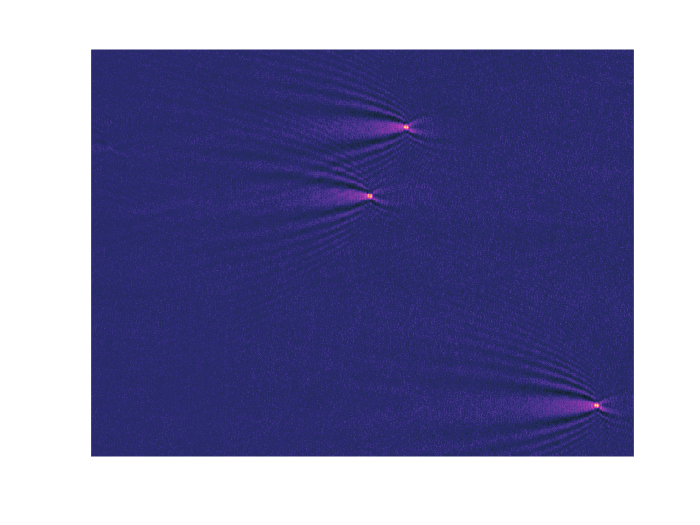

close all
clear all
clc
tiffpath = 'D:\work\散射场\实验数据\20220408_PsNPs_colission\PsNPs_300nm\BG';
tiffs = dir(fullfile(tiffpath,'*.tiff'));

BG = MVMExtBG(tiffpath);

I = double(imread(fullfile(tiffpath,tiffs(1).name))) - BG;

figure
imagesc(I);
axis off
axis equal
colormap(sunglow)

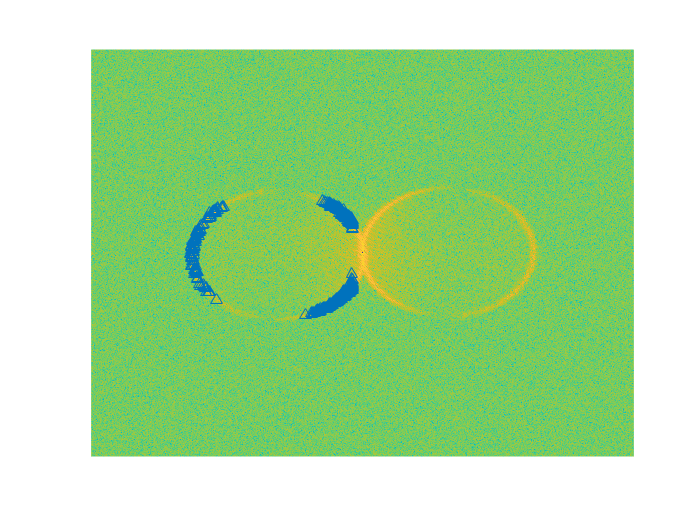

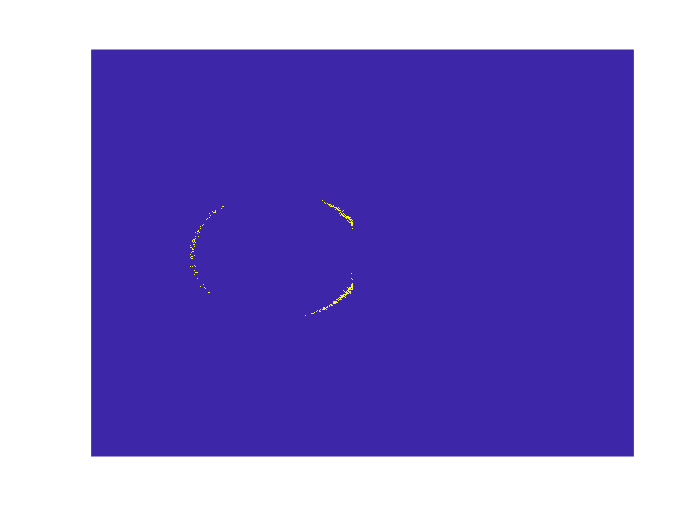


F = fftshift(fft2(I));
[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,1);

peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.15,'G',2);
I_rcn = (ifft2(ifftshift(F.*mask)));

## 剪切原图

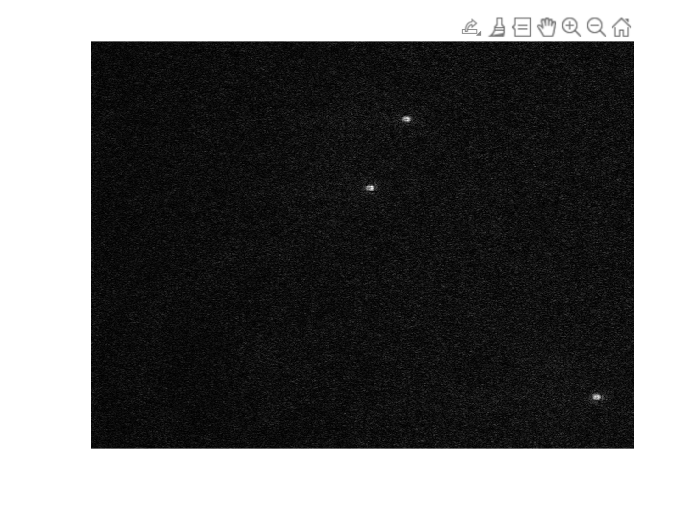

[I_amp,rectout] = imcrop(normalization(abs(I_rcn)));

I_real = imcrop(real(I_rcn)/max(real(I_rcn),[],'all'),rectout);
I_imag = imcrop(imag(I_rcn)/max(imag(I_rcn),[],'all'),rectout);
I_spr = imcrop(I/max(I(:)),rectout);

## 纳米颗粒-结果比较

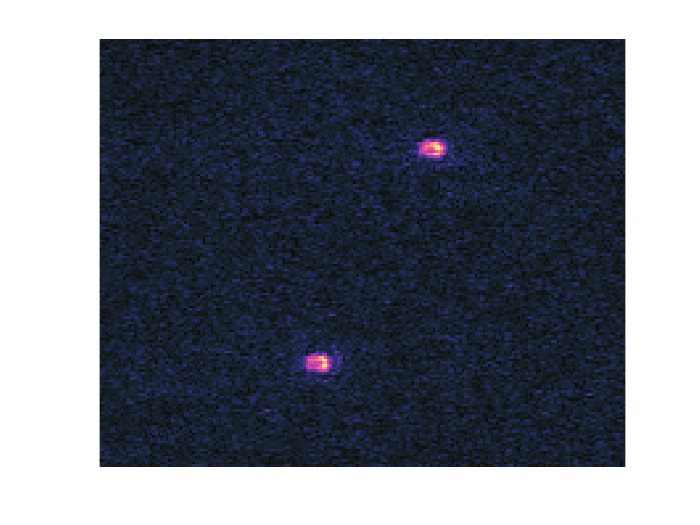

% 模值
figure
imagesc(I_amp)
axis off
axis equal
colormap(sunglow)

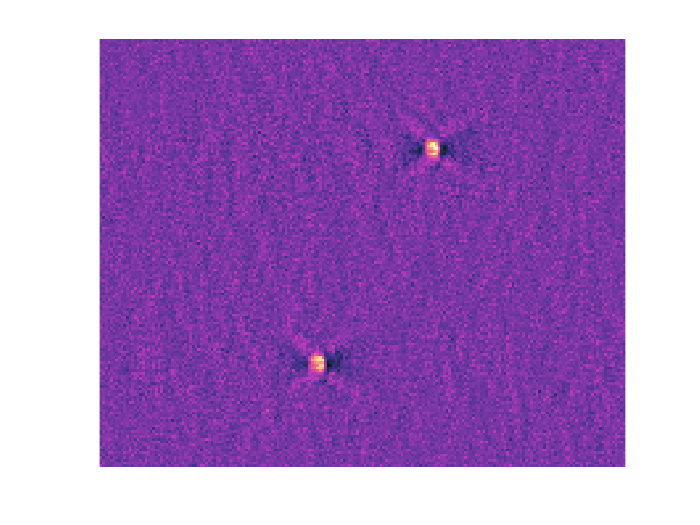

% 实部
figure
imagesc(I_real)
axis off
axis equal
colormap(sunglow)

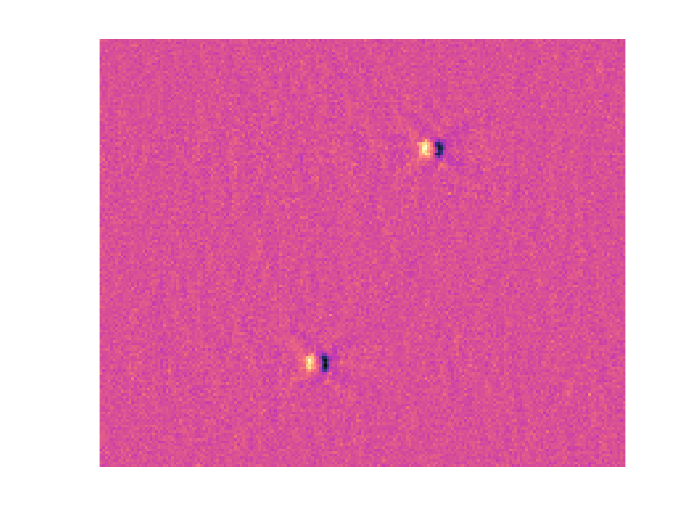

% 虚部
figure
imagesc(I_imag)
axis off
axis equal
colormap(sunglow)

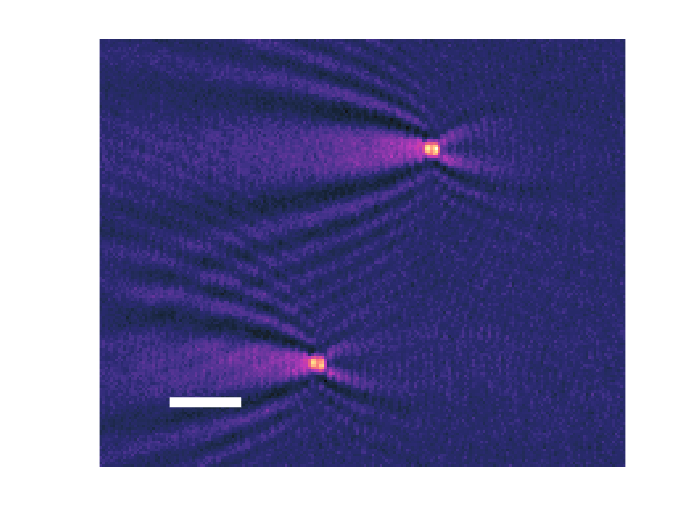

% SPRM
figure
imagesc(I_spr)
axis off
axis equal
colormap(sunglow)
line([27 27+2000/73.8],[138 138],'color','white','linewidth',6)     % scalebar，长2um

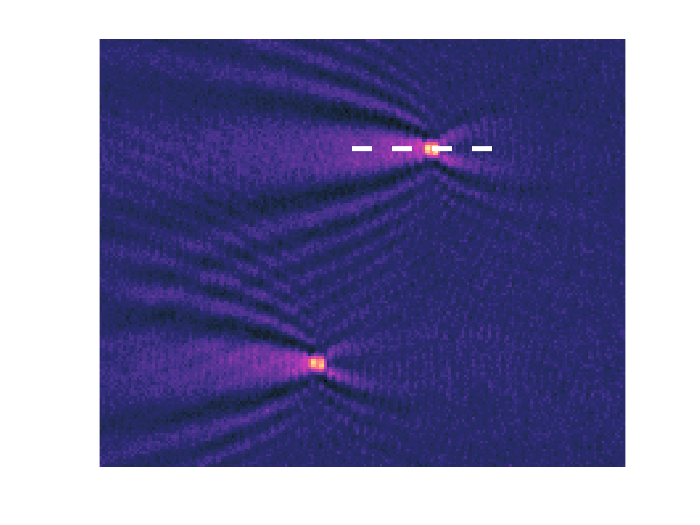


X = [96 156];
Y = [42 42];
int_spr = LineCut(I_spr,X,Y);

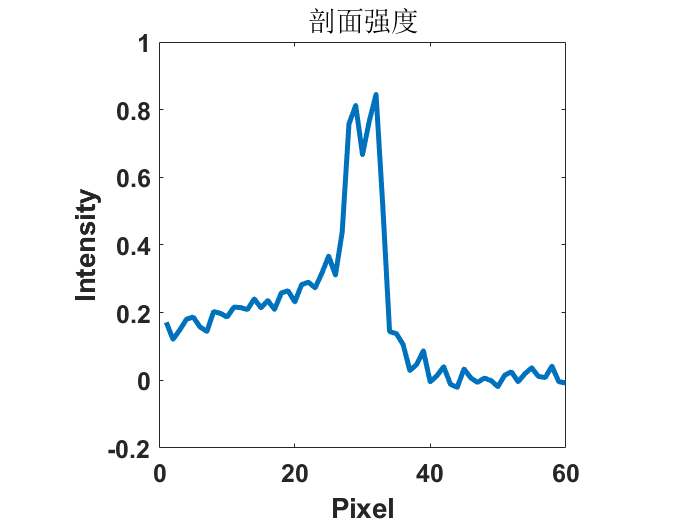

hold on

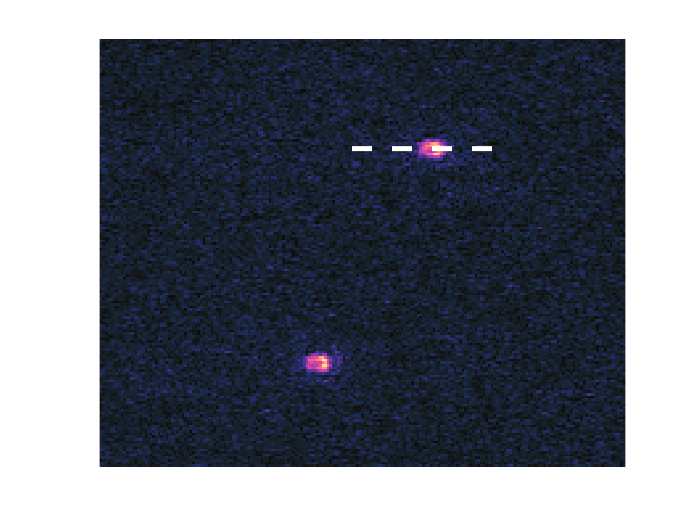

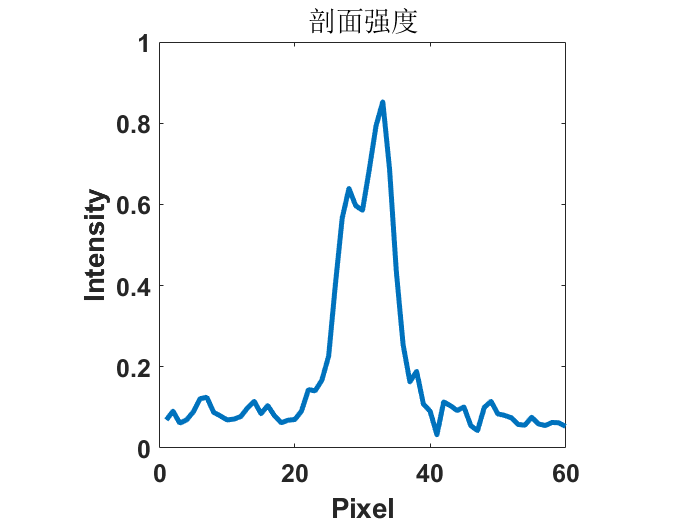

int_amp = LineCut(I_amp,X,Y);

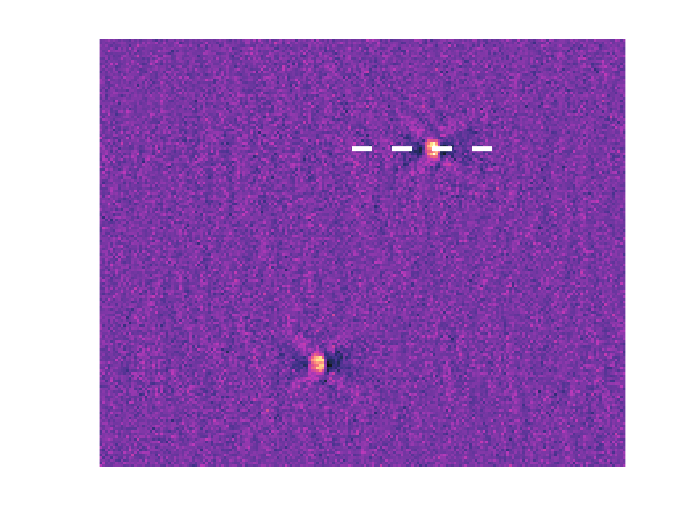

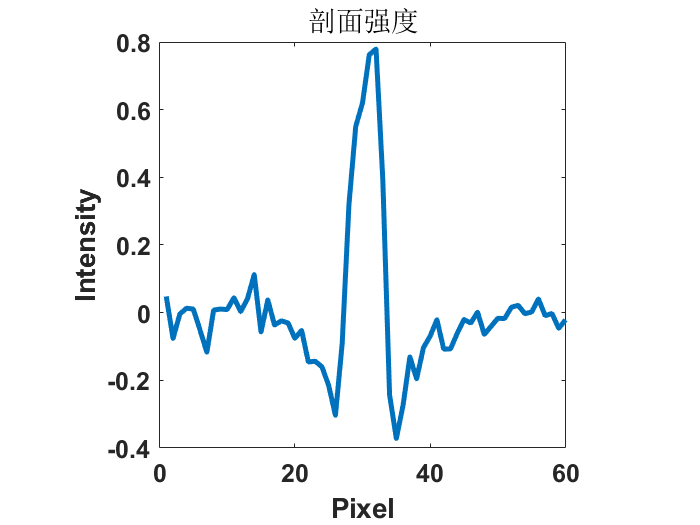

int_real = LineCut(I_real,X,Y);

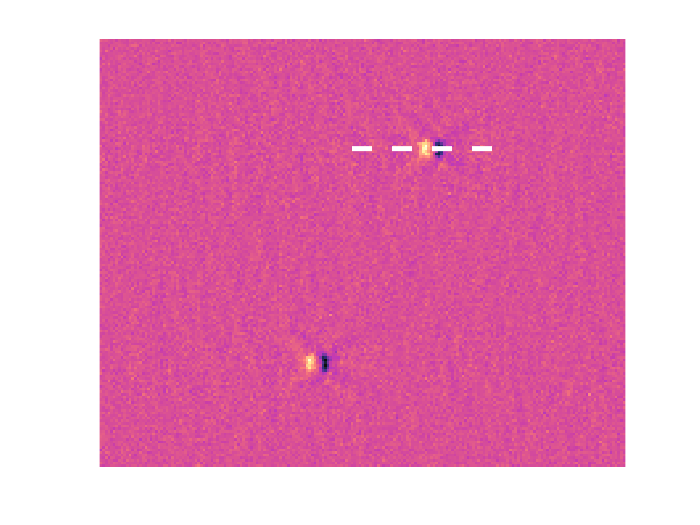

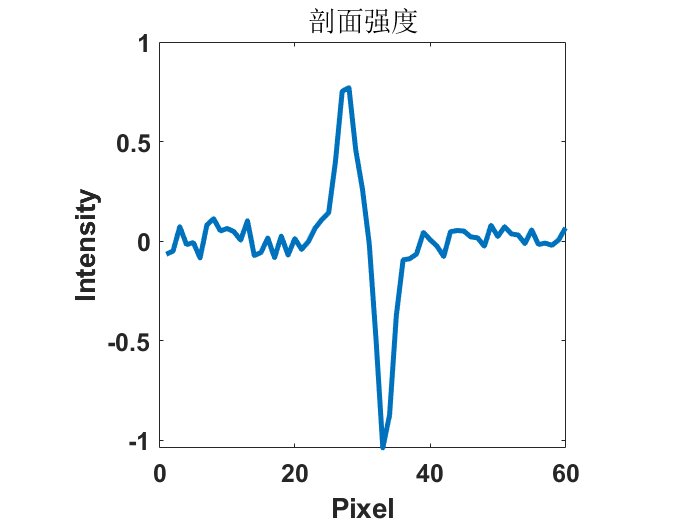

int_imag = LineCut(I_imag,X,Y);

## 作图

hl = findobj(gca,'type','line');
hl.YData = int_imag;

## 定义归一化函数

function norml_I = normalization(I)
    max_num = max(I(:));
    min_num = min(I(:));
    norml_I = (I - min_num)/(max_num - min_num);
end